# Elementos constantes Poisson

Solucion particular de la Ecuacion de Poisson

CONST=7;
Theta=linspace(0,2*pi,N);
Ufront= @(x,y)  CONST*exp(x)*sin(y);
Qfront= @(x,y)  CONST*(exp(x)*sin(y)*cos(Theta)*x+exp(x)*cos(y)*sin(Theta)*y);
N=100;

 **En este caso el dominio es una circunferencia**

xfront=zeros(N,1);
yfront=zeros(N,1);
Nodo=zeros(N+1,2);
Nodoz=zeros(N+1,3);
L=zeros(N,2);
normalz=zeros(N,3);
normaluniz=zeros(N,3);
norma=zeros(1,N);
P=zeros(N,2);
for i=1:N
    xfront(i)=CONST*cos(2*pi*(i-1)/N);%CONTS expande la elipse en el eje x
    yfront(i)=sin(2*pi*(i-1)/N);
    Nodo(i,:)=[xfront(i), yfront(i)];
    Nodoz(i,:)=[Nodo(i,:),0];         %para verlos como vectores de 3 componentes
end
Nodo(N+1,:)=Nodo(1,:); %identificamos el nodo 1 como el nodo N+1, esto para poder trabajar sobre el ultimo elemento
Nodoz(N+1,:)=Nodoz(1,:);
for i=1:N
    L(i,:)=Nodo(i+1,:)-Nodo(i,:);    %Vector que tiene la Longitud de los nodos
end
for i=i:N
    normalz(i,:)=cross(Nodoz(i+1,:)-Nodoz(i,:),[0,0,1]);
    norma(i)=norm(normalz(i,:));
    normaluniz(i,:)=normalz(i,:)/norma(i); %Normalizamos el vector
%calculo del punto sobre el cual va a estar centrada la solución fundamental y su derivada.
end
normaluniz(:,3)=[]; %elimina la tercera componente, ya sé que todas las terceras componentes son cero
normaluni=normaluniz; %Vuelvo a pasar todo a dos componentes.
for i=1:N
    P(i,:)= (Nodo(i,:)+Nodo(i+1,:))/2; %Punto medio del elemento
end


La solucion fundamental para n=2 en la ecuacion de laplace es


$$u_{i,j}^{*}(\zeta)=\frac{-1}{2\pi}Ln(|\zeta-P_{i}|) \quad \quad q_{i,j}^{*}(\zeta)=\frac{\partial u_{ij}^{*}}{\partial n}= \frac{-1}{2\pi} *\frac{\zeta-P_{i}}{|\zeta-P_{i}|^{2}}*n(\zeta)$$


Definamos a $$\bar H$$ 


$$$$\bar H_{ij}=\int_{\Gamma_{j}}q_{i,j}^{*} d\Gamma=\frac{-1}{2\pi}\int_{0}^{1} \frac{\gamma(t)-P_{i}}{|\gamma(t)-P_{i}|^{2}}*n(\gamma(t))*\|\gamma(t)\|dt, \quad \quad \gamma(t)=a+(b-a)t, \quad t\in[0,1] $$
$$


Definamos a $\bar G$


$$$$\bar G_{ij}=\int_{\Gamma_{j}}u_{i,j}^{*} d\Gamma=\frac{-1}{2\pi}\int_{0}^{1} \ln(|\gamma(t)-p_{i}|)*\|\gamma(t)\|dt, \quad \quad \gamma(t)=a+(b-a)t, \quad t\in[0,1] $$$$


donde se va a integrar por la cuadratura de Gauss de 4 puntos, en este caso para $$\bar H$$, así:


$$\int_{0}^{1}\frac{-1}{2\pi} *\frac{\gamma(t)-P_{i}}{|\gamma(t)-P_{i}|^{2}}*n(\gamma(t))dt=\frac{b-a}{2}\sum_{i=1}^{4}wq_{ij}(x) ,\quad \quad x=\frac{b-a}{2}+t\frac{b-a}{2}, \quad \quad t\in[-1,1]$$


Analogo para$\bar G$

barH=zeros(N,N);
G=zeros(N,N);
Baux=zeros(N,N);
Haux=zeros(4,1);
Gaux=zeros(4,1);
baux=zeros(4,1);
w=zeros(1,4);
a=0;
b=1;
for i=1:N
    for j=1:N
        if j==i
            barH(i,j)=0;
            G(i,j)= -norm(L(j,:))*(log(norm(L(j,:))/2)-1)/(2*pi);
        else
            %-Funciones que se van a integrar para encontrar barH->qij y G->uij
            uij = @(t) -(log(norm(Nodo(j,:)+t*(L(j,:))-P(i,:)))/(2*pi))*norm(L(j,:));
            qij = @(t) -(dot((Nodo(j,:)+t*(L(j,:))-P(i,:)),normaluni(j,:))*norm(L(j,:))/((norm(Nodo(j,:)+t*(L(j,:))-P(i,:)))^2))/(2*pi);
            b_uij=@(t) CONST*(-log(norm(Nodo(j,:)+t*(L(j,:))-P(i,:)))/(2*pi)*norm(L(j,:)));
            
            %INTEGRACIÓN POR CUADRATURA DE GAUSS
            [t,w]=Gausslp(4);
            x=((b-a)*t+a+b)/2; %deberia ser con la misma parametrizacion?
            M=length(x);
             
            for k=1:M
               Haux(k,:)=qij(x(k)); %evaluando en los 4 puntos qij(x)
               Gaux(k,:)=uij(x(k)); %evaluando en los 4 puntos uij(x)
               baux(k,:)=b_uij(x(k)); %evaluando en los 4 puntos uij(x)
            end
            barH(i,j)=w*Haux*(b-a)/2; %Resultado final del proceso de integración
            G(i,j)=w*Gaux*(b-a)/2; %Resultado final del proceso de integración
            Baux(i,j)=w*baux*(b-a)/2; %Resultado final del proceso de integración
        end
    end
end

Definamos a $H_{i j}=\bar{H}_{i j}+\frac{1}{2} \delta_{i j}\$ ,  se le suma $\frac{1}{2}
$ cuando $i=j$

idn=eye(N)/2;
H=idn+barH;

El sistema quedaria de la siguiente manera


$$\mathrm{Hu+Gc}=\mathrm{Gq}
$$


reescribiendolo tenemos


$$\mathrm{Hu}=\mathrm{G(q-c)}$$


Ademas,

Cuando k=0 se conoce el flujo "q" (Condiciones de Neumann) y se desconoce el potencial. Si k=N se conoce el potencial "u" (Condiciones de Dirichlet) y se desconoce el flujo. El algoritmo tambien sirve para condiciones de tipo Robin donde $k\in (0,N)$

Creacion de los vectores auxiliares con los datos conocidos. Los nodos donde no se conocen los datos se llenan con ceros.

**Variables conocidas sobre la frontera**

k=N;
Ufrontaux=zeros(1,N);
Qfrontaux=zeros(1,N);
VCONST=zeros(1,N);
for i=1:N
    VCONST(i)=CONST;
end

for i=1:N
    if i<=k
        Ufrontaux(i)=Ufront(P(i,1),P(i,2));
        Qfrontaux(i)=0;
     else
        Ufrontaux(i)=0;
        Qfrontaux=Qfront(P(i,1),P(i,2))-VCONST
    end
end
Ufrontaux=Ufrontaux';%De vector fila a vector columna
Qfrontaux=Qfrontaux'; %De vector fila a vector columna

Recordemos la ecuación $\mathbf{H u}=\mathbf{G q-G c}$ en este caso si k=0, solo se conoce $\mathbf{q}$, para encontrar $\mathbf{u}$, tenemos $\mathbf{u}=\mathbf{H^{-1}G(q-c)$,  si k=N tenemos conocida $\mathbf{u}$, para encontrar $\mathbf{q}$, tenemos $\mathbf{q}=\mathbf{G^{-1}Hu+c}$.

Si $k\in (0,N)$ se despeja en un lado las incognitas y en el otro las variables conocidas. Iniciando desde el nodo 1 hasta k indica hasta que nodo se conoce u sobre la frontera, entonces q se conocerá desde el nodo k+1 hasta el nodo N+1

**Variables desconocidas sobre la frontera**

A1=H(:,k+1:N);
A2=-G(:,1:k);
A=[A1 A2]; %se agrupan las incognitas para generar una matriz NXN

**Vector solucion de sistema sobre frontera**

Y=G*Qfrontaux-H*Ufrontaux; 

**Solucion del sistema** **lineal. **El vector X tiene las primeras k componentes los valores de q y los siguientes k+1 hasta N son valores de u.

X=A\Y;  
Qfrontaux(1:k,1)=X(1:k);
Ufrontaux(k+1:N,1)=X(k+1:N);

Se agrupan los valores conocidos y hallados.

Ufrontera=Ufrontaux;
Qfrontera=Qfrontaux;

# Puntos interiores

xint=zeros(1,10);
yint=zeros(1,10);
Pint=zeros(1,2);
Hauxint=zeros(4,1);
Gauxint=zeros(4,1);
for i=1:N
   Qfrontexac=Qfront(P(i,1),P(i,2));
end
Qfrontexac;
ErrorQ=norm(Qfrontera'-Qfrontexac)/norm(Qfrontexac)

ErrorQ = 1.6199

CÁLCULO DE U EN LOS PUNTOS INTERIORES

NI=20; %Número de nodos interiores a usar
%Elección de los puntos interiores
for i=1:10
    xint(i)=0.5*cos(2*pi*(i-1)/10);
    yint(i)=0.5*sin(2*pi*(i-1)/10);
    Pint(i,:)= [xint(i),yint(i)];
end

for i=1:10
    xint(i)=0.2*cos(2*pi*(i-1)/10);
    yint(i)=0.2*sin(2*pi*(i-1)/10);
    Pint(10 +i,:)= [xint(i),yint(i)];
end

%Calculo De H y G en los puntos interiores
a=0;
b=1;
for i=1:NI
    for j=1:N
        
            uijint = @(t) -log(norm(Nodo(j,:)+t*(L(j,:))-Pint(i,:)))/(2*pi)*norm(L(j,:));
            qijint = @(t) -(dot((Nodo(j,:)+t*(L(j,:))-Pint(i,:)),normaluni(j,:))*norm(L(j,:))/((norm(Nodo(j,:)+t*(L(j,:))-Pint(i,:)))^2))/(2*pi);
            [t,w]=Gausslp(4);
            x=((b-a)*t+a+b)/2;
            M=length(x);
            for k=1:M
               Hauxint(k,:)=qijint(x(k));
               Gauxint(k,:)=uijint(x(k));
                            
            end
            barHint(i,j)=w*Hauxint*(b-a)/2; 
            Gint(i,j)=w*Gauxint*(b-a)/2;       
    end
end

Uint=Gint*Qfrontera-barHint*Ufrontera;

for i=1:20
   UintExac=Ufront(Pint(i,1),Pint(i,2));
end

ErrorU=norm(Uint'-UintExac)/norm(UintExac)

ErrorU = 6.3372

GRÁFICA

Para que se vea como una superficie primero se debe crear una malla uniformemente espaciada. Los valores desconocidos se calculan interpolando los valores conocidos. 

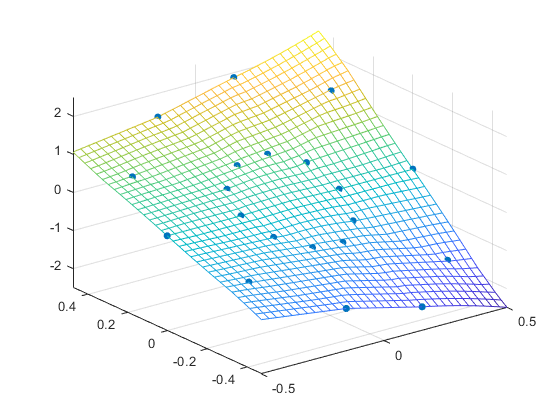

xlin = linspace(min(Pint(:,1)),max(Pint(:,1)),33); 
ylin = linspace(min(Pint(:,2)),max(Pint(:,2)),33);
[X,Y] = meshgrid(xlin,ylin); %creación de la malla uniforme
f = scatteredInterpolant(Pint(:,1),Pint(:,2),Uint); %proceso de interpolación
Z = f(X,Y);
figure
mesh(X,Y,Z) %Grafica de la malla uniforme con los valores interpolados
axis tight; hold on
plot3(Pint(:,1),Pint(:,2),Uint,'.','MarkerSize',15) %esto grafica los puntos originales (SOLO LOS PUNTOS)

function [t,w]=Gausslp(N)
b=zeros(1);
if N<0 
    print('\n Error!!!polinomio de orden negativo Gauss-Legendre??\n');
else
    t=roots(Lgndrp(N))'; % convertirlo en un vector fila
    A(1,:)= ones(1,N); b(1)=2;
    
    for n=2:N
        A(n,:)=A(n-1,:).*t;
    if mod(n,2)==0
        b(n)=0;
    else 
        b(n)=2/n; 
    end
    end
    w= b/A';
end 

    function p=Lgndrp(N) %Polinomio de Legrende
    if N<=0 
        p=1; %n*Ln(t)=(2n-1)t Ln-1(t)-(n-1)Ln-2(t) Eq.(5.9.6b)
    elseif N==1
        p=[1 0];
    else 
        p=((2*N-1)*[Lgndrp(N-1) 0]-(N-1)*[0 0 Lgndrp(N-2)])/N;
    end
end  
end
